clear;close all;
load('Figures\wavepath53m.mat');
% trace chosen for wavepath computation
itrace = idxTrace;
trace = csg0.seis(:, itrace);
% central frequency of Ricker
fc = mod1.fc; fmax = 1./mod1.dt; nt = double(mod1.nt);
trF = fft(trace)/length(trace);
A0 = max(abs(trF));

%% low pass filter: FIR
filtOrder = 100; fcut = 200;
lpFilt = designfilt('lowpassfir','FilterOrder', filtOrder, ...
         'SampleRate', fmax, 'CutoffFrequency', fcut);
delayFilt = round(mean(grpdelay(lpFilt)));
%fvtool(lpFilt);
trFilt = filter(lpFilt, trace);
trFilt(1:delayFilt) = [];
trFiltFFT = fft(trFilt)/length(trFilt);
% low pass filter: IIR
lpButter = designfilt('lowpassiir','FilterOrder',8, 'DesignMethod', 'butter', ...
         'HalfPowerFrequency',fcut,'SampleRate',fmax);
trButter = filtfilt(lpButter, trace);
trButterFFT = fft(trButter)/length(trButter);


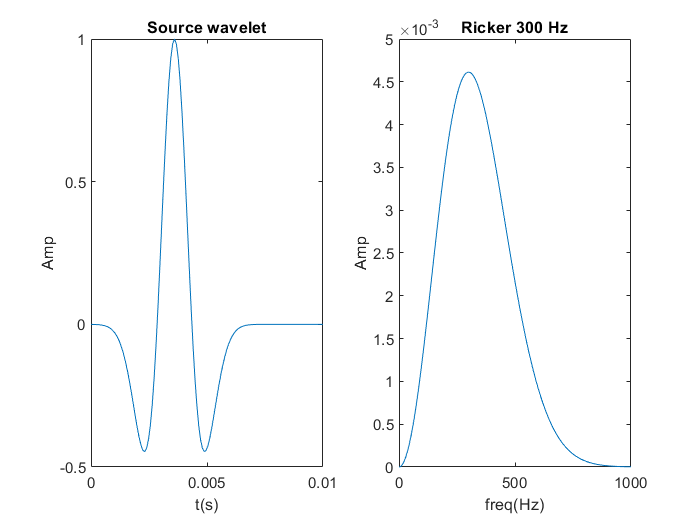

%% plotting
t = mod1.dt * (0:nt-1);
wav = zeros(1, nt);
nwav = length(csg0.wavelet);
wav(1:nwav) = csg0.wavelet;
fwav = (0:nt-1) * mod1.df;
wavF = fft(wav)/length(wav);
figure(1);
subplot(1,2,1);
plot(t, wav);
xlim([0, 0.01]);
xlabel('t(s)'); ylabel('Amp');
title('Source wavelet');
subplot(1,2,2);
plot(fwav, abs(wavF));
xlim([0, 1000]);
xlabel('freq(Hz)'); ylabel('Amp');
title('Ricker 300 Hz');

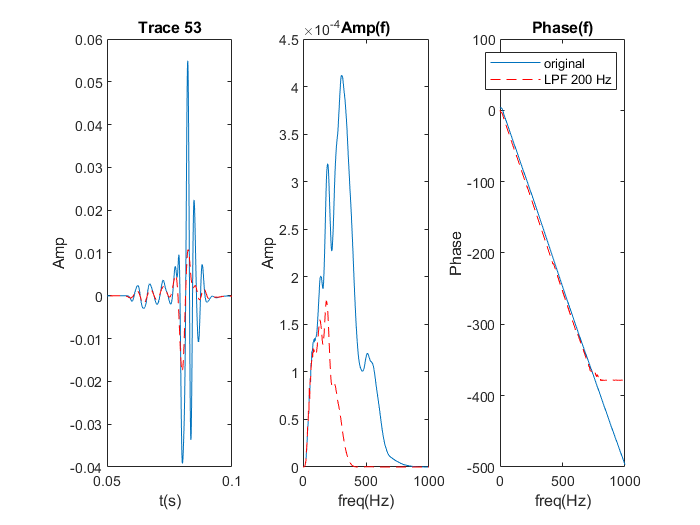

figure(2);
subplot(1,3,1);
plot(t(1:end-delayFilt), trace(1:end-delayFilt)); hold on; 
plot(t(1:end-delayFilt), trFilt, 'r--'); hold off;
xlabel('t(s)'); ylabel('Amp');
xlim([0.05, 0.1]);
title(sprintf('Trace %d', itrace));
subplot(1,3,2);
plot(fwav, abs(trF)); hold on; 
plot(fwav(1:end-delayFilt), abs(trFiltFFT), 'r--'); hold off;
xlim([0, 1000]);
xlabel('freq(Hz)'); ylabel('Amp');
title('Amp(f)');
subplot(1,3,3);
plot(fwav, unwrap(angle(trF))); hold on; 
plot(fwav(1:end-delayFilt), unwrap(angle(trFiltFFT)), 'r--'); hold off;
xlim([0, 1000]);
xlabel('freq(Hz)'); ylabel('Phase');
title('Phase(f)');
legend('original', sprintf('LPF %d Hz', fcut));

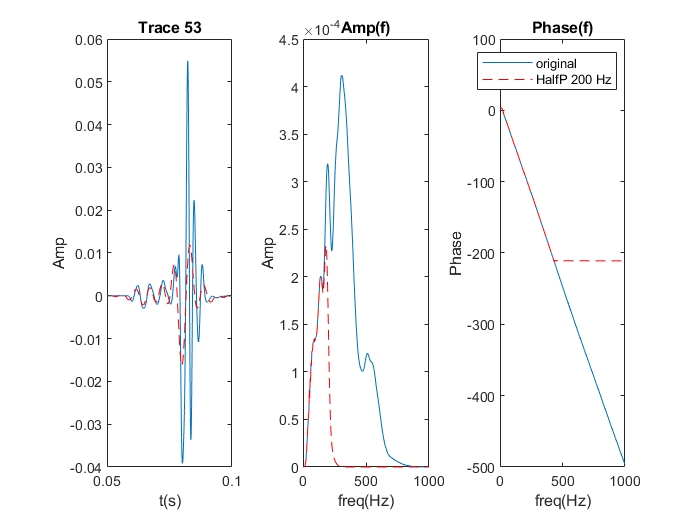

figure(3);
subplot(1,3,1);
plot(t, trace); hold on; 
plot(t, trButter, 'r--'); hold off;
xlabel('t(s)'); ylabel('Amp');
xlim([0.05, 0.1]);
title(sprintf('Trace %d', itrace));
subplot(1,3,2);
plot(fwav, abs(trF)); hold on; 
plot(fwav, abs(trButterFFT), 'r--'); hold off;
xlim([0, 1000]);
xlabel('freq(Hz)'); ylabel('Amp');
title('Amp(f)');
subplot(1,3,3);
plot(fwav, unwrap(angle(trF))); hold on; 
plot(fwav, unwrap(angle(trButterFFT)), 'r--'); hold off;
xlim([0, 1000]);
xlabel('freq(Hz)'); ylabel('Phase');
title('Phase(f)');
legend('original', sprintf('HalfP %d Hz', fcut));